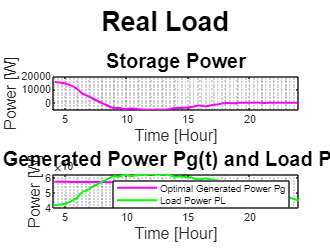

print = 1;
chosen = 57;
offset = 15;
day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(chosen,:);
E_max = Storage_size(5);

%% Real Load
YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset+1:end),sigma2023,mu2023,E_max,print,'Real Load','Optimal Generated Power Pg(t) and Load Power PL(t)','Optimal Generated Power Pg','Load Power PL');

print = 1;
chosen = 57;
offset = 15;
%% LSTM Prediction
YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(chosen,:),sigma2023,mu2023,E_max,print,'LSTM Prediction','Generated Power Pg(t) and Forecasted Load Power PL(t)','Generated Power Pg','Forecasted Load Power PL');

Unrecognized function or variable 'Predictions_LSTM_2023'.

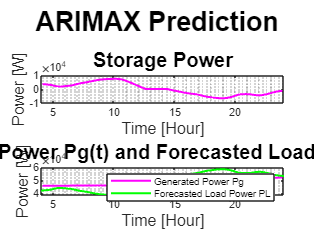


%% ARIMAX Prediction
% Predictions_ARIMAX_2023_transposed = (Predictions_ARIMAX_2023_transposed - mu_arima) ./ sigma_arima;
YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(chosen,:),sigma_arima,mu_arima,E_max,print,'ARIMAX Prediction','Generated Power Pg(t) and Forecasted Load Power PL(t)','Generated Power Pg','Forecasted Load Power PL');